# IRS-assisted 802.11ad link 

This code integrates an IRS module within a 802.11ad link. As described in Fig. 1, the link comprises an access point (AP) with non-line-of-sight (NLoS) coonection to the mobile user (MU). The connection is made by the line-of-sight (LoS) connection between the AP and IRS, and between the IRS and the MU.

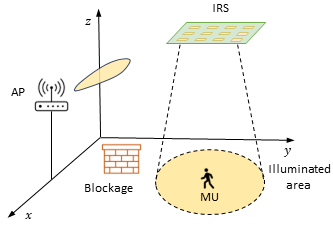

Fig 1: IRS-assisted link between an access point (AP) and a mobile user (MU).

The code is divided in three modules as for the IRS settings, the evaluation of the SNR in the ground plane, and the evaluation of the age of information (AoI). Results are illustrated as plots in the `results` folder. The files used to implement these blocks are the following

- `Parameters` file: This file evaluates all the parameters for the system model. Parameters such as the position of the communication components, communication frame slots following the 802.11as std, power and noise levels, and the mobility of the user.

- `IRS_config` file: This file compute the pathloss and the SNR in the link AP-IRS-MU as observed by the MU.

- IRS_802_11ad file: This file implements the link AP-IRS-MU and evaluates the SNR at the packet error rate (PER) at the MU position within the 802.11ad std.

- `simulation_results`: This file stores the calculation of the pathloss, SNR, PER, observed at the MU position with its radius from the cneter of the illuminated area. This results are evaluated by the `IRS_802_11ad` file and using the Parameters. The pathloss, SNR, PER are stored as arrays with the same name, which represent matrices of 50x50. Each row refers

#### Evaluating the SNR in ground plane

Description: This block evaluates the SNR observed at the ground plane with the center coordinates already specified in the `Parameters` file. The SNR is evaluated for the complete link AP-IRS-MU.

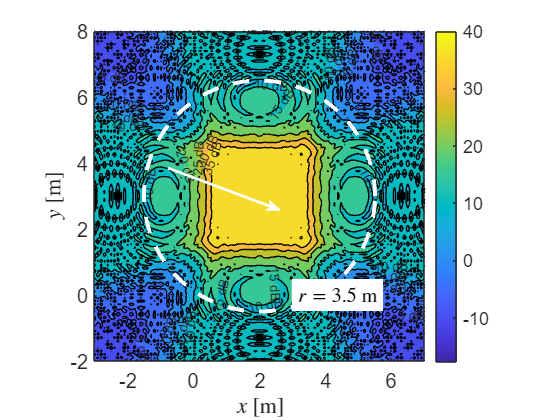

close all;

%running the scripts for the simulation parameters
Parameters
%evaluating the IRS coefficients
IRS_config

%conforming the grid in the xy-plane
y_points = p_center(2)+grid_point;
z_points = p_center(3)+grid_point;
[Y,Z]=meshgrid(y_points,z_points);

[M,c]=contourf(Y,Z,pow2db(SNR),"ShowText",true); hold on;
colorbar
c.LabelFormat="%0.0f dB";
c.LabelSpacing=1000;
c.FaceAlpha=1;

%plotting the circle or radius r
center=[2 3];
r = 3.5;% radius
q = 0:0.01:2*pi; % angle 0 to 360 degrees in radian
x = r*cos(q)+center(1);    % cartesian x coordinate
y = r*sin(q)+center(2);    % cartesian y coordinate
plot(x,y,'Color','white','LineStyle','--','LineWidth',3);

annotation("arrow",[0.3 0.5],[0.6 0.5],'Color','white','LineWidth',2);
text(3.1,0,strcat('$r=',num2str(r),'$ m'),'Interpreter','latex','FontSize',fontsize,'BackgroundColor','white');

axis square
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%saving the plot to the results folder
saveas(gcf, './results/IRS.fig');

Error using saveas
Invalid or missing path: ../results/IRS.fig

saveas(gcf, './results/IRS.svg');


#### **Evaluating the SNR & Pathloss vs radius in the ground plane**

Description: This block  evaluate the PER observed at the MU position. The PER is evaluated with the radius from the center of the illuminated area. The plot is obtained 

Parameters
load simulation_results.mat

figure;
SNR_r=zeros(1,total_pos_points);
pathloss_r=zeros(1,total_pos_points);
for i_radius=1:total_pos_points
    SNR_r(i_radius)=mean(SNR_radius_ang(i_radius,:));
    pathloss_r(i_radius)=mean(pathloss(i_radius,:));
end

plot(r_MU,pow2db(SNR_r),'LineWidth',2);grid on;

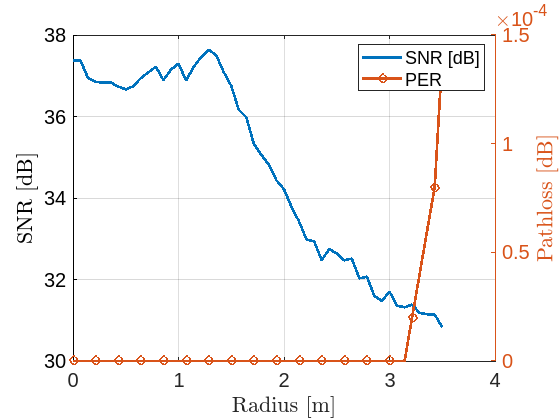

xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);

yyaxis right
plot(r_MU,mean(PER,2),'o-','LineWidth',2,'MarkerIndices',1:3:length(r_MU));grid on;
ylabel('Pathloss [dB]','Interpreter','latex');

legend('SNR [dB]','PER');

**SNR & distance vs radius**

figure;
fontsize=15;

SNR_r_min=pow2db(min(SNR,[],1)+10);
SNR_r_max=pow2db(max(SNR,[],1));

%calculating the mean SNR
SNR_r=zeros(1,total_pos_points);
for i_radius=1:total_pos_points
    SNR_r(i_radius)=mean(SNR(i_radius,:));

end

figure;
xconf = [r_MU r_MU(end:-1:1)] ;         
yconf = [SNR_r_max SNR_r_min(end:-1:1)];
p = fill(xconf,yconf,'red');
p.FaceColor = [1 0.8 0.8];      
p.EdgeColor = 'none';
p.FaceAlpha=0.5

plot(r_MU,pow2db(SNR_r),'LineWidth',2);grid on; hold on
xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);


figure;


% for i_radius=1:total_pos_points
%     distance_AP_IRS_MU(i_radius)=norm([x_pos_UE r_MU(i_radius) 0]...
%         -pos_ris);
% end
% distance_AP_IRS_MU=distance_AP_IRS_MU+norm(pos_ap-pos_ris);

plot(r_MU,SNR_r,'LineWidth',2);grid on;
xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);

yyaxis right
plot(r_MU,distance_AP_IRS_MU,'o-','LineWidth',2,'MarkerIndices',1:3:length(r_MU));grid on;
ylabel('Distance [m]','Interpreter','latex');

legend('SNR [dB]','Distance AP-IRS-MU');

% for i_r=1:total_pos_points
%     for i_an=1:total_pos_points
%         plot3(r_MU(i_r).*cos(angle_MU(i_an)),r_MU.*sin(angle_MU(i_an)),SNR(i_r,i_an),'o');hold on;
%     end
% end
% scatter(r_MU.*cos(angle_MU),r_MU.*sin(angle_MU),[],'filled','ColorVariable',SNR);
% Table=[r_MU.*cos(angle_MU)',r_MU.*sin(angle_MU)',SNR'];
% T=array2table(Table);
% s = scatter(T,'Table1','Table2','filled','ColorVariable','Table3');
% s.SizeData = 50;
% colorbar
% clim([-10 45])


**Throughput  & SNR vs radius**

figure;
plot(r_MU,SNR_r,'LineWidth',2);grid on;
xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);

yyaxis right
plot(r_MU,throughput,'o-','LineWidth',2,'MarkerIndices',1:3:length(r_MU));grid on;
ylabel('Throughput [Mbps]','Interpreter','latex');

legend('SNR [dB]','Throughput [Mbps]');


**PER  & SNR vs radius**

figure;
plot(r_MU,SNR_r,'LineWidth',2);grid on;
xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);

yyaxis right
plot(r_MU,mean(PER,2),'o-','LineWidth',2,'MarkerIndices',1:3:length(r_MU));grid on;
ylabel('PER','Interpreter','latex');

legend('SNR [dB]','PER');

**Moving video**

figure;
tile=tiledlayout(5,1);
% tile.TileSpacing = 'compact';
% tile.Padding = 'compact';
nexttile([3 1]);
% subplot 211
plot3(p_AP(1),p_AP(2),p_AP(3),'o','MarkerFaceColor','#0072BD');hold on;
plot3(p_IRS(1),p_IRS(2),p_IRS(3),'o','MarkerFaceColor','#D95319'); grid on;
p=plot3(pos_ue(1),pos_ue(2),pos_ue(3),'o','MarkerFaceColor','#000000'); grid on;
%MU path
h_MU = animatedline;
h_MU.LineWidth=0.5;
h_MU.Color="#000000";

xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
zlabel('$z$ [m]','Interpreter','latex');
legend('AP','IRS','MU');
% legend("Position", [0.25,0.8,0.2,0.2])
set(gca,'FontSize',fontsize)
axis([-7 15 -10 10 -10 10]);
axis square;

%SNR
nexttile([2 1]);
v_MU=1;
delta_t=r_MU(2)/v_MU;
plot(delta_t,SNR_r(1),'LineWidth',2); grid on;
h_SNR = animatedline;
h_SNR.LineWidth=2;
h_SNR.Color="#0072BD";
xlabel('Time [s]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize)

SNR_tick=linspace(min(SNR_r)-1,max(SNR_r)+1,3);
set(gca, 'YTick', SNR_tick);
y_ticks=cell(1,3);
for m=1:length(SNR_tick)
  y_ticks{m}=strcat(num2str(SNR_tick(m),2));
end
set(gca, 'YTickLabel', y_ticks, 'TickLabelInterpreter', 'latex');
axis([0 delta_t*total_pos_points^2 min(SNR_r)-1 max(SNR_r)+1]);

%path loss
yyaxis right
% plot(delta_t,norm(pos_ap-pos_ris)+norm(pos_ris-pos_ue));
plot(delta_t,pathloss_r(1));
h_norm = animatedline;
h_norm.LineWidth=2;
h_norm.Color="#D95319";
ylabel('Pathloss [dB]','Interpreter','latex');
axis([0 delta_t*total_pos_points^2 min(pathloss_r)-1 max(pathloss_r+1)])
% axis([0 delta_t*total_pos_points^2 ...
%       norm(pos_ap-pos_ris)+norm(pos_ris-[pos_ue(1),0,0])...
%       norm(pos_ap-pos_ris)+norm(pos_ris-[pos_ue(1) 0 r_MU(end)])]);

n=0;
for i_radius=1:total_pos_points
    for i_ang=1:total_pos_points
        %MU position
        pos_ue(2)=r_MU(i_radius)*cos(angle_MU(i_ang));
        pos_ue(3)=r_MU(i_radius)*sin(angle_MU(i_ang));
        
        set(p,'YData',pos_ue(2),'ZData',pos_ue(3),'MarkerFaceColor','#000000');
        %MU path
        addpoints(h_MU,pos_ue(1),pos_ue(2),pos_ue(3));
        %distance AP-IRS-MU
%         addpoints(h_norm,n*delta_t,norm(pos_ap-pos_ris)+norm(pos_ris-pos_ue));
        
        n=n+1;
        drawnow;
    end
    %SNR
    addpoints(h_SNR,n*delta_t,SNR_r(i_radius));
    %pathloss
    addpoints(h_norm,n*delta_t,pathloss_r(i_radius));
    
end

%view([196.66 32.01]);

view([329.32 49.72])

